# Bridge of Doom

## Exercise 36.1

clc, clear, clf
syms beta t
assume(beta, {'real', 'positive'});
assume(t, {'real', 'positive'});

global r T_hat N_hat beta_num V_L V_R t_num

r_i = 4*(.3960*cos(2.65*((beta*t)+1.4)));
r_j = -4 * (.99*sin((beta*t)+1.4));
r_k = 0*t;

r = [r_i, r_j, r_k];

dr_dt = simplify(diff(r,t));
T_hat = simplify(dr_dt./norm(dr_dt));

dT_dt = simplify(diff(T_hat, t));
N_hat = simplify(dT_dt./norm(dT_dt));

beta_num = .04;

t_num = linspace(0, 3.2 / beta_num, 100);
x_num = linspace(0, 3.2 / beta_num, 10);

for n=1:length(t_num)
    r_num(n,:) = double(subs(r, {beta, t}, {beta_num, t_num(n)}));
    T_hat_num(n,:) = double(subs(T_hat, {beta, t}, {beta_num, t_num(n)}));
    N_hat_num(n,:) = double(subs(N_hat, {beta, t}, {beta_num, t_num(n)}));
    
    hold on
    plot(r_num(:,1), r_num(:,2), 'blue'); axis([-5 5 -5 5])
    
    if (ismember(t_num(n), x_num))
        quiver(r_num(n,1), r_num(n,2), N_hat_num(n,1), N_hat_num(n,2), 'red');
        quiver(r_num(n,1), r_num(n,2), T_hat_num(n,1), T_hat_num(n,2), 'green');
    end  
    hold off    
    drawnow
end

## Exercise 36.2

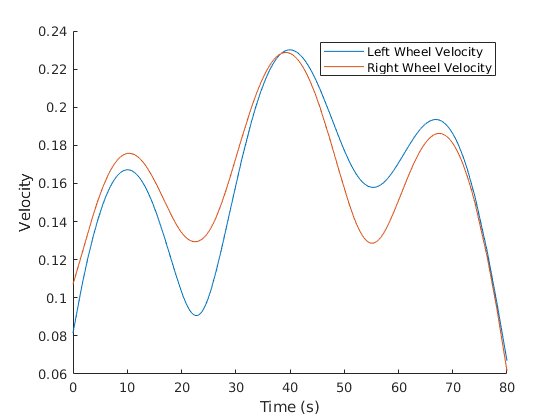

clf

omega = simplify(cross(T_hat, dT_dt));
V = simplify(norm(dr_dt));
d = .235;

V_L = simplify(V - omega(:,3)*d/2);
V_R = simplify(V + omega(:,3)*d/2);

V_L = subs(V_L, {beta}, {beta_num});
V_R = subs(V_R, {beta}, {beta_num});

figure
hold on
fplot(V_L)
fplot(V_R)
hold off
xlim([0 3.2 / beta_num])
legend('Left Wheel Velocity', 'Right Wheel Velocity')
xlabel('Time (s)')
ylabel('Velocity')

## Exercise 36.3

linear_velocity = (V_L + V_R) / 2

$$linear\_velocity = \frac{1683\,\sqrt{2500\,{\cos\left(\frac{17\,t}{50}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{901\,t}{1000}+\frac{371}{100}\right)}^{2}}}{62500}$$

angular_velocity = (V_R - V_L) / 2

$$angular\_velocity = -\frac{42347\,\left(182500\,\cos\left(\frac{119\,t}{1000}+\frac{49}{100}\right)+764917\,\cos\left(\frac{561\,t}{1000}+\frac{231}{100}\right)+327837\,\cos\left(\frac{1241\,t}{1000}+\frac{511}{100}\right)+82500\,\cos\left(\frac{1921\,t}{1000}+\frac{791}{100}\right)-205057\,\cos\left(\frac{2363\,t}{1000}+\frac{973}{100}\right)-92697\,\cos\left(\frac{3043\,t}{1000}+\frac{1253}{100}\right)\right)}{16000\,{\left(2500\,\cos\left(\frac{17\,t}{25}+\frac{14}{5}\right)-2809\,\cos\left(\frac{901\,t}{500}+\frac{371}{50}\right)+5309\right)}^{2}}$$

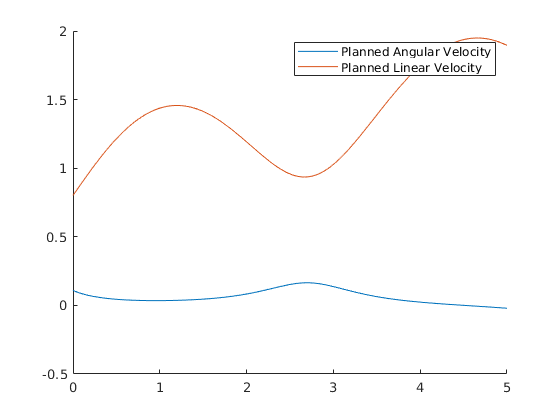


figure
hold on
fplot(angular_velocity)
fplot(linear_velocity)
legend('Planned Angular Velocity', 'Planned Linear Velocity')
hold off

## Exercise 36.4